# This MATLAB live script provides details of modeling and analysis of the benchmark **25-bar truss **optimization problems.

**By: **Mohammad Farshchin, Ph.D.

**Email: **Mohammad.Farshchin@gmail.com

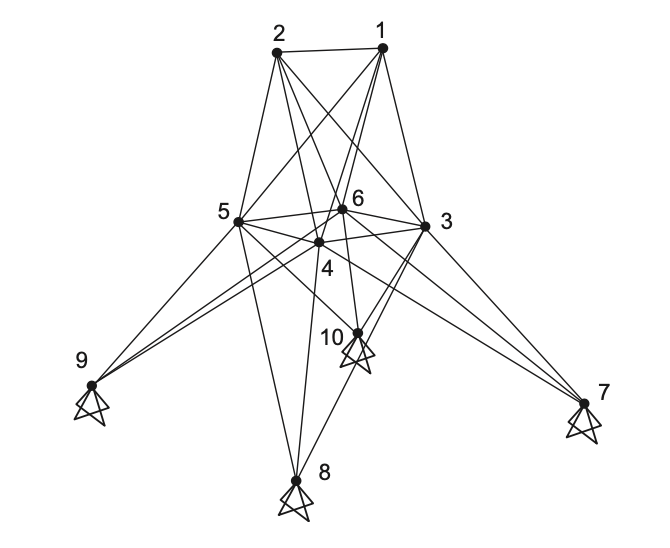

### **For detailed information about this benchmark problem refer to the following paper:**

- Camp, C.V. & Farshchin, M. (2014). [Design of space trusses using modified teaching-learning based optimization](http://www.sciencedirect.com/science/article/pii/S0141029614000236), Engineering Structures 62-63, 87-97

### **Please also refer to the following publications for information about several optimization algorithms to optimize this problems:**

- Farshchin, M., Maniat, M., Camp, C.V., & Pezeshk, S. (2018). [School based optimization algorithm for design of steel frames](https://www.sciencedirect.com/science/article/pii/S0141029617308787), Engineering Structures, Volume 171, 326-335.

- Farshchin, M., Camp, C.V., & Maniat, M. (2016). [Multi-class teaching–learning-based optimization for truss design with frequency constraints](http://www.sciencedirect.com/science/article/pii/S0141029615006732), Engineering Structures, Volume 106, 1, 355-369.

- Farshchin, M., Camp, C.V., & Maniat, M. (2016). [Optimal design of truss structures for size and shape with frequency constraints using a collaborative optimization strategy](https://www.sciencedirect.com/science/article/pii/S0957417416304900), Expert Systems with Applications, Vol 66.

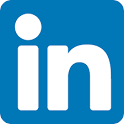 [https://www.linkedin.com/in/mfarshchin/](https://www.linkedin.com/in/mfarshchin/)          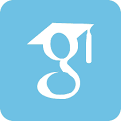 [https://scholar.google.com/citations?user=ZYO6CwEAAAAJ&hl=en](https://scholar.google.com/citations?user=ZYO6CwEAAAAJ&hl=en)

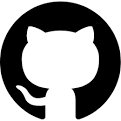 [https://github.com/mfarshchin](https://github.com/mfarshchin)                         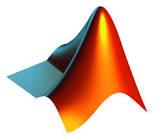 [https://www.mathworks.com/matlabcentral/profile/authors/3727592-mohammad-farshchin](https://www.mathworks.com/matlabcentral/profile/authors/3727592-mohammad-farshchin)

## Benchmark 1: 25-bar truss problem with *discrete* design variables

Configuration of the 25-bar benchmark truss is shown in the figure above. For additional details please refere to [this](http://www.sciencedirect.com/science/article/pii/S0141029614000236) publication.

**Important note:** members of this truss are grouped into eight groups. Also there is one load combination for this discrete design optimization problem.

**Main scripts for modeling and analysis:** 

- **DisData25.m  **Properties of 25-bar truss (e.g. geometry, loading, boundary conditions, penalty function, etc) with discrete design variables are defined in this function 

- **ST25D.m** This function is to run the analysis for a 25-bar truss with discrete design variables

The following set of commands are to run the 25-bar truss for a randomly generated design

clear
D=DisData25; % Define the truss (geometry, connectivity, etc)
ConDesign=[0.12, 0.27, 3.42, 0.09, 2.12, 0.98, 0.52, 3.36]; % Define a random design (section area for each group of elements)
fprintf('Random design vector is: \n\n'),disp(ConDesign)

Random design vector is: 

    0.1200    0.2700    3.4200    0.0900    2.1200    0.9800    0.5200    3.3600



First step is to map this desing to a viable design with discrete design variables. See DisData25.m for available sections (D.AV)

for I=1:size(ConDesign,2)
    [~,b]=min(abs(D.AV-ConDesign(1,I))); %D.AV contains available sections (See DisData25.m)
    DisDesign(1,I)=D.AV(b);
end
fprintf('Discrete design vector is: \n\n'),disp(DisDesign)

Discrete design vector is: 

    0.1000    0.3000    3.4000    0.1000    2.1000    1.0000    0.5000    3.4000



The second step is to assign this desing to the elements in each group.

for J=1:size(D.Group,1)
    Design(D.Group{J},:)=DisDesign(J);
end

Now we can run the analysis

% Analyze the design and compte the total weight of truss (Weight, lbs) and objective value (penalized weight) 
[Weight,Objective]=ST25D(Design,D);
% print the design
fprintf('Truss Design is: \n\n'),disp(Design')

Truss Design is: 

  Columns 1 through 15

    0.1000    0.3000    0.3000    0.3000    0.3000    3.4000    3.4000    3.4000    3.4000    0.1000    0.1000    2.1000    2.1000    1.0000    1.0000

  Columns 16 through 25

    1.0000    1.0000    0.5000    0.5000    0.5000    0.5000    3.4000    3.4000    3.4000    3.4000



fprintf('Truss weight is: %6.4f lbs\n',Weight);

Truss weight is: 484.8542 lbs


fprintf('Penalized weight (Objective value) is: %6.4f\n',Objective);

Penalized weight (Objective value) is: 484.8542


Note: for details of penalty function check out the DisData25.m file

## Benchmark 2: 25-bar truss problem with *continuous* design variables and multiple load cases

Configuration of the 25-bar benchmark truss is shown in the figure above. For additional details please refere to [this](http://www.sciencedirect.com/science/article/pii/S0141029614000236) publication.

**Important note:** members of this truss are grouped into eight groups. Also there are two load combination for this continuous design optimization problem.

**Main scripts for modeling and analysis:** 

- **Data25.m  **Properties of 25-bar truss (e.g. geometry, loading, boundary conditions, penalty function, etc) with continuous design variables are defined in this function 

- **ST25C.m** This function is to run the analysis for a 25-bar truss with continuous design variables and multiple load cases

The following set of commands are to run the 25-bar truss for a randomly generated design

clear
D=Data25; % Define the truss (geometry, connectivity, etc)
ConDesign=[0.01, 2.00, 3.00, 0.01, 0.01, 0.70, 1.60, 2.70]; % Define a random design (section area for each group of elements)
fprintf('Random design vector is: \n\n'),disp(ConDesign)

Random design vector is: 

    0.0100    2.0000    3.0000    0.0100    0.0100    0.7000    1.6000    2.7000



Assign this desing to the elements in each group.

for J=1:size(D.Group,1)
    Design(D.Group{J},:)=ConDesign(J);
end

Now we can run the analysis

% Analyze the design and compte the total weight of truss (Weight, lbs) and objective value (penalized weight) 
[Weight,Objective]=ST25C(Design,D);
% print the design
fprintf('Truss Design is: \n\n'),disp(Design')

Truss Design is: 

  Columns 1 through 15

    0.0100    2.0000    2.0000    2.0000    2.0000    3.0000    3.0000    3.0000    3.0000    0.0100    0.0100    0.0100    0.0100    0.7000    0.7000

  Columns 16 through 25

    0.7000    0.7000    1.6000    1.6000    1.6000    1.6000    2.7000    2.7000    2.7000    2.7000



fprintf('Truss weight is: %6.4f lbs\n',Weight);

Truss weight is: 543.7295 lbs


fprintf('Penalized weight (Objective value) is: %6.4f\n',Objective);

Penalized weight (Objective value) is: 675.9327


Note: for details of penalty function check out the Data25.m file